Purpose: 

1. Scan through elements of a vector and write output to a file based on an element satisfying a condition.

 2. Plot a Piecewise Function

 3.  Solve a system of linear equations if system is not singular

clc, clear
 Problem = menu('Choose a Problem','Problem 1','Problem 2','Problem 3');
 if Problem == 1
    fid1 = fopen('outPositive.dat','w');
    fid2 = fopen('outNegative.dat','w');
   fprintf(fid1,'====================================================== \n');
    fprintf(fid1,'Element(s) whose values lie between 3 and 7 (inclusive) \n');
     fprintf(fid1,'======================================================= \n');
     fprintf(fid2,'Element(s) out of range (3 → 7) \n');
     fprintf(fid2,'================================ \n');
    
    Low = 3; High = 7;
    rowV = randi([2,14],1,3);
    for j = 1:3
     x = rowV(j);
         if (x >=Low) && (x<=High)
        y = 1;
          fprintf(fid1,'integer(%.0f) = %.0f, y = %.0f \n', j, x, y);
         else
        y = -1;
        fprintf(fid2,'integer(%.0f) = %.0f, y = %.0f \n', j, x, y);
        end
    
    end
    fclose('all');
    type  outPositive.dat
     type  outNegative.dat
 elseif Problem == 2
fprintf('Problem 2: Plot a Piecewise Function')
  figure(2)
    plotPieceWiseThursday
 else 

Problem 3: Find point of intersection of a two straight lines. 

figure(2)
 A = [2, -3
    -4, 2];


Apply the backslash method if and only if the coefficient determinant is not zero.


$$2x-3y=0$$



$$-4x+2y=-8$$


detA = det(A);
        if detA == 0
            fprintf(' The matrix is singular and a solution does not exist. \n');
        else
             fprintf('Problem 3: Point of intersection of two straight lines.\n');
        fprintf('=======================================================\n');
                fprintf(' The determinant %.2f is not zero so a unique solution exists. \n',detA);
            b = [0; -8];
            xy = A\b;   % store the x- and y-values at the intersection
        end
       fprintf(' The solution to the system is x = %.2f, y = %.2f \n',xy);

Plot the equations and the intersection point. Since the equations represent a straight line, optimize  compile time by using two points on the line.  

Select x-values that embrace the point of intersection.

Problem 3: Point of intersection of two straight lines.


 The determinant -8.00 is not zero so a unique solution exists. 


 The solution to the system is x = 3.00, y = 2.00 


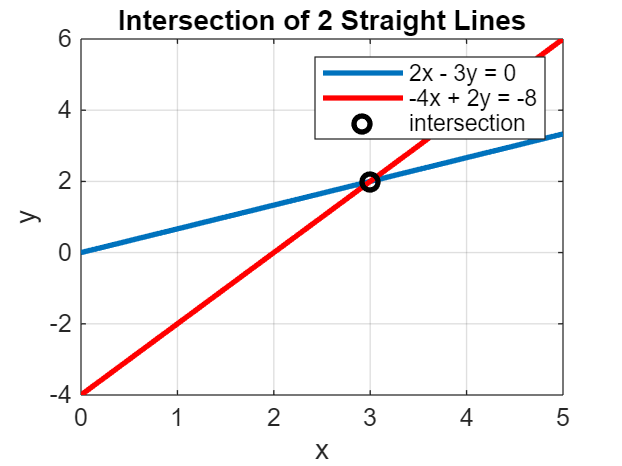

x = linspace(0,5,10);
    y1 = 2*x/3;
    y2 = 2*x - 4;
    plot(x,y1,x,y2,'r',xy(1),xy(2),'ko',LineWidth= 2)
    xlabel('x'), ylabel('y'), title('Intersection of 2 Straight Lines')
    grid
    legend('2x - 3y = 0','-4x + 2y = -8','intersection')
 end